## Homework 08 Root Finding

### 1. Use zero-, first-, second- and third-order Taylor series expansions to predict$f\left(2\right)$

### 
$$f\left(x\right)=25x^3 -6x^2 +7x-88$$


%Initialization Workspace
clear
clc
close
hold on
lineStyle = {':','-','--'};

%Initial Function
syms x
function_x(x) = 25*(x^3) - 6*(x^2) + 7*x - 88

$$function\_x(x) = 25\,x^{3}-6\,x^{2}+7\,x-88$$

trueValue_2 = function_x(2)

$$trueValue\_2 = 102$$

Using a base point at x = 1 and step size = 0.1, 0.5, 1 with **Backward Divided Difference.**


$$f^{\left(n\right)} \left(x\right)=\frac{\bigtriangledown_h^n \left\lbrack f\right\rbrack \left(x\right)}{h^n }=$$
 
$$\frac{1}{h^n }$$
 
$$\sum_{k=0}^n {\left(-1\right)}^k$$

$${n\choose k}$$

$$f\left(x-kh\right)$$


%Initial Condition
STEP_SIZE = [0.1, 0.5, 1];
x_i = 1;
x_target = 2;

Calculate the error for each of the Taylor series expansions


$$f\left(x_{i+1} \right)=\sum_{n=0}^{\infty } \frac{f^{\left(n\right)} \left(x_i \right)}{n!}{\left(x_{i+1} -x_i \right)}^n$$


%Error
syms trueValue approximationValue
error(trueValue,approximationValue) = ((trueValue - approximationValue)/trueValue);


$$\textrm{error}=\frac{\textrm{trueV}\textrm{alue}-\textrm{approximatedV}\textrm{alue}}{\textrm{trueV}\textrm{alue}}$$


#### Zero-Order Taylor Series Expansion

#### 
$$f\left(x_{i+1} \right)\cong f\left(x_i \right)$$


order = 0;

for i = 1:size(STEP_SIZE,2)
    h = STEP_SIZE(i);
    
    approximationValue = taylorSeries_dividedDifference_backward(function_x, ...
        x_i,x_target,order,h);
    
    l0 = plot([x_i x_target],[function_x(x_i) approximationValue], 'r', 'LineWidth', 1.5);
    plot(x_target,approximationValue, 'o', 'MarkerFaceColor', 'r','MarkerEdgeColor','none')
    
    fprintf(['Approximation Value (Taylor + Backward Zero-Order Step %0.2f)' ...
        '  : %0.2f \t error : %0.2f\n'], ...
        STEP_SIZE(i), approximationValue, error(trueValue_2,approximationValue))
end

Approximation Value (Taylor + Backward Zero-Order Step 0.10) : -62.00 	 error : 1.61


Approximation Value (Taylor + Backward Zero-Order Step 0.50) : -62.00 	 error : 1.61


Approximation Value (Taylor + Backward Zero-Order Step 1.00) : -62.00 	 error : 1.61


#### One-Order Taylor Series Expansion

#### 
$$f\left(x_{i+1} \right)\cong f\left(x_i \right)+f^{\prime } \left(x_i \right)\left(x_{i+1} -x_i \right)$$


order = 1;
for i = 1:size(STEP_SIZE,2)
    h = STEP_SIZE(i);
    
    approximationValue = taylorSeries_dividedDifference_backward(function_x, ...
        x_i,x_target,order,h);
    
    l1(i) = plot([x_i x_target],[function_x(x_i) approximationValue], 'g', 'LineWidth', 0.5*i);
    plot(x_target,approximationValue, 'o', 'MarkerFaceColor', 'g','MarkerEdgeColor','none')
    
    fprintf(['Approximation Value (Taylor + Backward First-Order Step %0.2f)' ...
        '  : %0.2f \t error : %0.2f\n'], ...
        STEP_SIZE(i), approximationValue, error(trueValue_2,approximationValue))
end

Approximation Value (Taylor + Backward First-Order Step 0.10) : 1.35 	 error : 0.99


Approximation Value (Taylor + Backward First-Order Step 0.50) : -20.25 	 error : 1.20


Approximation Value (Taylor + Backward First-Order Step 1.00) : -36.00 	 error : 1.35


#### Second-Order Taylor Series Expansion

#### 
$$f\left(x_{i+1} \right)\cong f\left(x_i \right)+f^{\prime } \left(x_i \right)\left(x_{i+1} -x_i \right)+\frac{f^{\prime \prime } \left(x_i \right){\left(x_{i+1} -x_i \right)}^2 }{2!}$$


order = 2;

for i = 1:size(STEP_SIZE,2)
    h = STEP_SIZE(i);
    
    approximationValue = taylorSeries_dividedDifference_backward(function_x, ...
        x_i,x_target,order,h);
    
    l2(i) = plot([x_i x_target],[function_x(x_i) approximationValue], 'b', 'LineWidth', 0.5*i);
    plot(x_target,approximationValue, 'o', 'MarkerFaceColor', 'b','MarkerEdgeColor','none')
    
    fprintf(['Approximation Value (Taylor + Backward Second-Order Step %0.2f)' ...
        '  :%0.2f \t error : %0.2f\n'], ...
        STEP_SIZE(i), approximationValue, error(trueValue_2,approximationValue))
end

Approximation Value (Taylor + Backward Second-Order Step 0.10) :62.85 	 error : 0.38


Approximation Value (Taylor + Backward Second-Order Step 0.50) :11.25 	 error : 0.89


Approximation Value (Taylor + Backward Second-Order Step 1.00) :-42.00 	 error : 1.41


#### Third-Order Taylor Series Expansion

#### 
$$f\left(x_{i+1} \right)\cong f\left(x_i \right)+f^{\prime } \left(x_i \right)\left(x_{i+1} -x_i \right)+\frac{f^{\prime \prime } \left(x_i \right){\left(x_{i+1} -x_i \right)}^2 }{2!}+\frac{{{f^{\prime } }^{\prime } }^{\prime } \left(x_i \right){\left(x_{i+1} -x_i \right)}^3 }{3!}$$


order = 3;

for i = 1:size(STEP_SIZE,2)
    h = STEP_SIZE(i);
    
    approximationValue = taylorSeries_dividedDifference_backward(function_x, ...
        x_i,x_target,order,h);
    
    l3(i) = plot([x_i x_target],[function_x(x_i) approximationValue], 'm', 'LineWidth', 0.5*i);
    plot(x_target,approximationValue, 'o', 'MarkerFaceColor', 'm','MarkerEdgeColor','none')
    
    fprintf(['Approximation Value (Taylor + Backward Third-Order Step %0.2f)' ...
        '  : %0.2f \t error : %0.2f\n'], ...
        STEP_SIZE(i), approximationValue, error(trueValue_2,approximationValue))
end

Approximation Value (Taylor + Backward Third-Order Step 0.10) : 87.85 	 error : 0.14


Approximation Value (Taylor + Backward Third-Order Step 0.50) : 36.25 	 error : 0.64


Approximation Value (Taylor + Backward Third-Order Step 1.00) : -17.00 	 error : 1.17


### Summary Plot

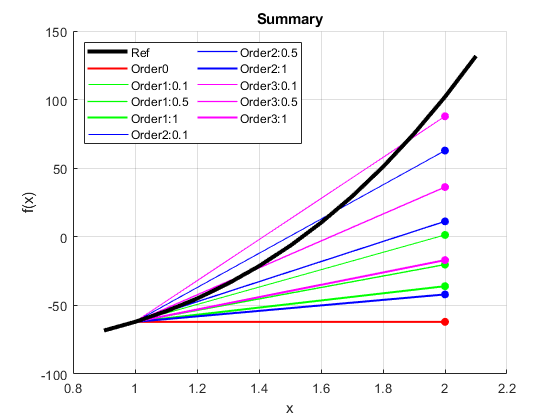

x_p = x_i-0.1:0.1:x_target+0.1;

title('Summary');
grid on;
xlabel('x');
ylabel('f(x)');

ref = plot(x_p,function_x(x_p), 'black', 'LineWidth', 3);
legend([ref, l0 ,l1(1) ,l1(2) ,l1(3) ,l2(1) ,l2(2), l2(3), l3(1), l3(2), l3(3)], ...
    ["Ref","Order0","Order1:0.1","Order1:0.5","Order1:1","Order2:0.1", ...
    "Order2:0.5","Order2:1","Order3:0.1","Order3:0.5","Order3:1"], ...
    'Location','northwest','NumColumns',2)
hold off

### 2. Write a computer program that find the root of 

### 
$$f\left(x\right)=x^3 -3x^2 +1$$
 

%Initialization Workspace
clear
clc
close

%Initial Function
syms function_x x
function_x(x) = (x^3) - 3*(x^2) + 1

$$function\_x(x) = x^{3}-3\,x^{2}+1$$

### by using both bisection and false-position method in period $\left\lbrack 0,2\right\rbrack$

### and terminate the program when approximated

### relative error $\varepsilon_a \le 1%$  the program must generate a report file, 

syms epsilon_a approximationValue_previous approximationValue_present
epsilon_a(approximationValue_previous,approximationValue_present) = ( ...
    (approximationValue_present - approximationValue_previous)/ ...
    approximationValue_present)*100;

### report.txt, that shows in each line: 

(1) the number of iterations, 

(2) an estimated root in each iteration, 

(3) the approximate relative error in each iteration.

path = matlab.desktop.editor.getActiveFilename;
index = max(strfind(path,'\'));
filePart = extractBetween(path,1,index);
fileID = fopen(strcat(filePart{1},'report.txt'),'w');

hold on;

## Bracketing Method: Bisection Method


x_lower = 0;
x_upper = 2;

x_root_previous  = 0;
error_approximation = 100;

i = 1;

fprintf(fileID,'Bracketing Method: Bisection Method  \n');

%Algorithm Approximation Value Bisection Method
while error_approximation > 1
    
    x_root = (x_lower + x_upper)/2;
    approximationValue_root = function_x(x_lower) * function_x(x_root);
    
    if approximationValue_root < 0
        x_upper = x_root;
    elseif approximationValue_root > 0
        x_lower = x_root;
    end
    
    error_approximation = abs(epsilon_a(x_root_previous,x_root));
    
    mark1 = plot(x_root,approximationValue_root,'o', 'MarkerFaceColor', 'g','MarkerEdgeColor','none');
    
    fprintf(fileID,['Iteration : %i \t\t Estimated root : %0.4f \t\t ' ...
        'Approximate Relative Error : %0.4f \n'], ...
        i,x_root,error_approximation);
    
    i = i + 1;
    x_root_previous = x_root;
end

Iteration : 1 		 Estimated root : 1.0000 		 Approximate Relative Error : 100.0000 


Iteration : 2 		 Estimated root : 0.5000 		 Approximate Relative Error : 100.0000 


Iteration : 3 		 Estimated root : 0.7500 		 Approximate Relative Error : 33.3333 


Iteration : 4 		 Estimated root : 0.6250 		 Approximate Relative Error : 20.0000 


Iteration : 5 		 Estimated root : 0.6875 		 Approximate Relative Error : 9.0909 


Iteration : 6 		 Estimated root : 0.6563 		 Approximate Relative Error : 4.7619 


Iteration : 7 		 Estimated root : 0.6406 		 Approximate Relative Error : 2.4390 


Iteration : 8 		 Estimated root : 0.6484 		 Approximate Relative Error : 1.2048 


Iteration : 9 		 Estimated root : 0.6523 		 Approximate Relative Error : 0.5988 


## Bracketing Method: False-Position Method

x_lower = 0;
x_upper = 2;

x_root_previous  = 0;
error_approximation = 100;

i = 1;

fprintf(fileID,'\n\nBracketing Method: False-Position Method  \n');

%Algorithm Approximation Value False-Position Method
while error_approximation > 1
    
    approximationValue_lower = function_x(x_lower);
    approximationValue_upper = function_x(x_upper);
    
    x_root = (x_lower * approximationValue_upper - x_upper * approximationValue_lower)/( ...
        approximationValue_upper - approximationValue_lower);
    
    approximationValue_root = function_x(x_root);
    
    if approximationValue_root < 0
        x_upper = x_root;
    elseif approximationValue_root > 0
        x_lower = x_root;
    end
    
    error_approximation = abs(epsilon_a(x_root_previous,x_root));
    
    mark2 = plot(x_root,approximationValue_root,'o', 'MarkerFaceColor', 'r','MarkerEdgeColor','none');
    
    fprintf(fileID,['Iteration : %i \t\t Estimated root : %0.4f \t\t ' ...
        'Approximate Relative Error : %0.4f \n'], ...
        i,x_root,error_approximation);
    
    i = i + 1;
    x_root_previous = x_root;
end

Iteration : 1 		 Estimated root : 0.5000 		 Approximate Relative Error : 100.0000 


Iteration : 2 		 Estimated root : 0.6667 		 Approximate Relative Error : 25.0000 


Iteration : 3 		 Estimated root : 0.6517 		 Approximate Relative Error : 2.2989 


Iteration : 4 		 Estimated root : 0.6527 		 Approximate Relative Error : 0.1552 


fclose(fileID);

### Summary Plot

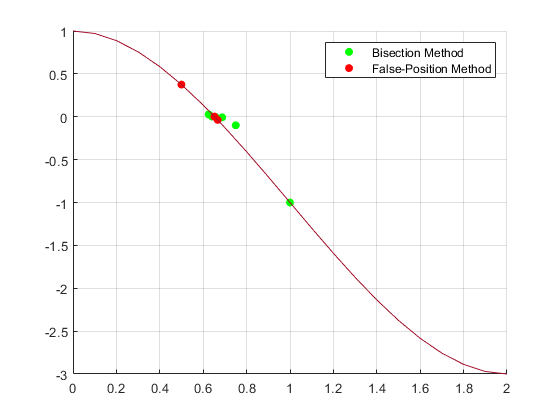

plot(0:0.1:2,function_x(0:0.1:2));grid on;hold off;
legend([mark1,mark2],["Bisection Method","False-Position Method"])

## Appendix

### Binomial coefficient

### 

syms n k
nchoosek(n,k);

### **Backward Divided Difference Taylor Series**


$$f\left(x_{i+1} \right)=\sum_{n=0}^{\infty } \frac{f^{\left(n\right)} \left(x_i \right)}{n!}{\left(x_{i+1} -x_i \right)}^n$$



$$f^{\left(n\right)} \left(x\right)=\frac{\bigtriangledown_h^n \left\lbrack f\right\rbrack \left(x\right)}{h^n }=$$
 
$$\frac{1}{h^n }$$
 
$$\sum_{k=0}^n {\left(-1\right)}^k$$

$${n\choose k}$$

$$f\left(x-kh\right)$$


function approximationValue = taylorSeries_dividedDifference_backward(function_x, x_i, ...
    x_target, order, h)

%Taylor Series
clear term_taylorSeries dividedDifference_backward_order
for n = 0:order
    
    %Divided Difference Backward
    clear term_dividedDifference_backward
    for k = 0:n
        term_dividedDifference_backward(k+1) = (((-1)^k) * nchoosek(n,k) * ...
            function_x(x_i - k*h));
    end
    dividedDifference_backward_order(n+1) = sum(term_dividedDifference_backward) / (h^n);
    %Divided Difference Backward END
    
    term_taylorSeries(n+1) = ( ...
        dividedDifference_backward_order(n+1) / factorial(n)) * ((x_target - x_i)^n);
end

approximationValue = sum(term_taylorSeries);
%Taylor Series END

end